# Compute Frequency Response

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity.

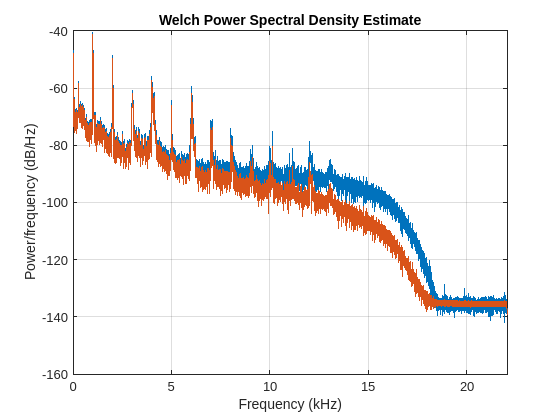

[whaley, fs] = audioread("./data/whalesound.wav");
b = [0.2 0.5 0.2];
whalefilt = filter(b, 1, whaley);
pwelch([whaley whalefilt], [], [], [], fs);

## Task 1

You can calculate the frequency response of a digital filter using the `freqz` function, which is based on the FFT operation:

`freqz``(``b``,``a``,``n``,``fs``)`

`n` is the number of evaluation points, or DFT points.

As you saw in the *Estimating Power Spectral Density* module, a larger number of evaluation points is more accurate but comes at the expense of computation time. When choosing the number of evaluation points, you should specify a power of 2 so that a more efficient FFT implementation can be used.

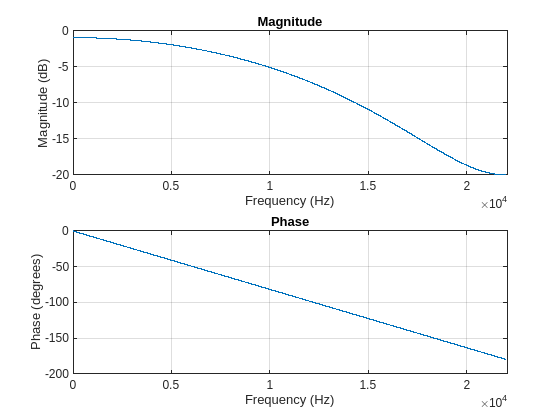

freqz(b, 1, 4096, fs)

## Task 2

If you're not sure how many points to use, for most filters you can use the default value of 512:

`freqz``(``b``,``a``,``[]``,``fs``)`

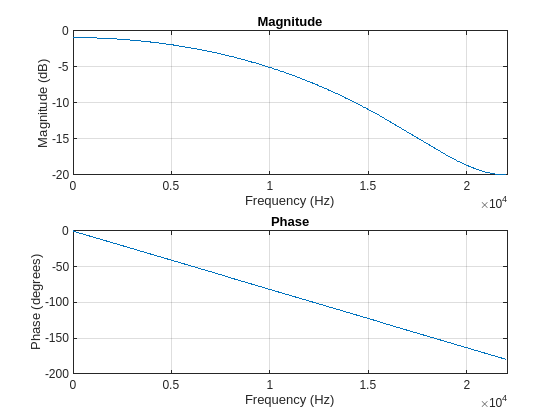

freqz(b, 1, [], fs)

## Task 3

The group delay is the negative first derivative of the phase response, and it shows you the delay introduced by the filter at each frequency in units of samples. If the phase response is linear, like this filter, the group delay is constant, and the signal is delayed by the same number of samples.

The inputs are the same as `freqz`:

`grpdelay``(``b``,``a``,``n``,``fs``)`

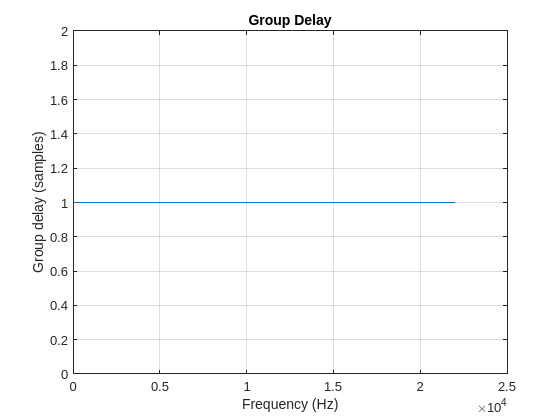

grpdelay(b, 1, [], fs)